% Visualize IED from awake-state SEEG data
clc; clear; close all; addpath z_toolbox;
addpath 'H:\project_manger\xlz_toolbox\fieldtrip-20231220';
ft_defaults;
subG = {'sub-0001', 'sub-0002', 'sub-0003', 'sub-0004', 'sub-0005', ...
    'sub-0007', 'sub-0008', 'sub-0009', 'sub-0010', 'sub-0011', ...
    'sub-0012', 'sub-0013', 'sub-0014', 'sub-0015', 'sub-0016', ...
    'sub-0017', 'sub-0019', 'sub-0020', 'sub-0021', 'sub-0022', ...
    'sub-0023', 'sub-0028', 'sub-0029', 'sub-0031', 'sub-0033', ...
    'sub-0034', 'sub-0035', 'sub-0036', 'sub-0039', 'sub-0046', ...
    'sub-0047', 'sub-0050', 'sub-0052', 'sub-0054', 'sub-0062', ...
    'sub-0063', 'sub-0066', 'sub-0067', 'sub-0074', 'sub-0077', ...
    'sub-0087', 'sub-0089', 'sub-0092', 'sub-0093', 'sub-0094', ...
    'sub-0113', 'sub-0115'};
seegPath = 'step2_SEEG_TCAR_BPF';
% subject ID
nS = 2; subID = subG{nS};
iEEGfileDir = dir(fullfile(seegPath, subID, ...
    [subID, '_task-rest_run-*_TCAR_BPF.mat']));
load(fullfile(iEEGfileDir(1).folder, iEEGfileDir(1).name));
% Channel selection
cfg = [];
cfg.channel = {'ta10', 'ta12', 'th10'};
data = ft_preprocessing(cfg, data);

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds


% Bandpass filtering
cfg = [];
cfg.detrend = 'yes';
cfg.demean = 'yes';
cfg.baselinewindow = 'all';
cfg.bpfilter = 'yes';
cfg.bpfreq = [10, 60]; 
cfg.bpfiltord = 3; 
data = ft_preprocessing(cfg, data);

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds


% ==== IED detection ====
pksPromTD = 3;
pksN2PdiffCTD = 6;
TDwinSize = 300;
IEDwinSize = 0.1;
IEDs = f_IED_detection(data, pksPromTD, pksN2PdiffCTD, TDwinSize, IEDwinSize);

****IED Detection Start!!!!
.-.. / --- / -. / --. / --.. / .... / --- / ..- // -..- / ..-
****2025-11-25 20:57:40
---------------------------------------------------------------
---------------------------------------------------------------
****IED Detection Completed!!!!
.-.. / --- / -. / --. / --.. / .... / --- / ..- // -..- / ..-
****2025-11-25 20:57:40


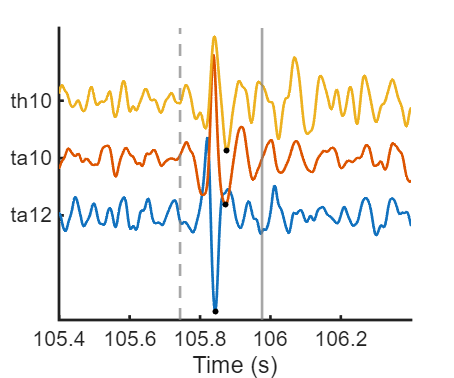

% ==== IED view ====
figure('Units', 'centimeters', 'Position', [5, 5, 12, 10]);
AX = axes; timeWinBE = [105400, 106400];
VoltageScale = 1;
[AX, timeWinBE, timeWin, signalsWin] = f_viewSignals(AX, data, timeWinBE, VoltageScale);
hold on;
IEDsinfo = IEDs.IEDsinfo{1};
IEDsinfoWin_time = f_viewIED(AX, IEDsinfo, timeWinBE, timeWin);
IEDraster = IEDs.IEDraster{1};
[IEDrasterWin_time, IEDrasterWin_value] = ...
    f_viewIEDnegPeak(AX, IEDraster, timeWinBE, timeWin, signalsWin);
hold off;
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);